%lab 2 matlab Thomas Wilson B00836766
vin = 1

vin = 1

R = 47

R = 47

L= 47e-6

L = 4.7000e-05


g1 = tf( R, [L R]) %Creating the tranferfunction for the RL circuit

g1 =
 
        47
  --------------
  4.7e-05 s + 47
 
Continuous-time transfer function.



t = linspace (0, 10e-6, 1000)%This is creating the time vector going from 0to 10 microseconds

t = 1.0e-05 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


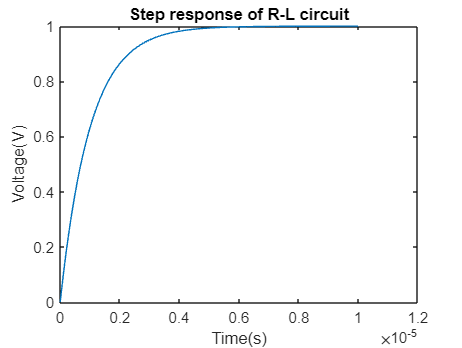

Vin = ones(size(t)) ;%this simulates the response of the RL circuit using step function
Vout = step(g1, t);% the output is the determained from the input with the use of the transfere function
plot(t, Vout)
title('Step response of R-L circuit' )
xlabel ('Time(s)');
ylabel('Voltage(V)');

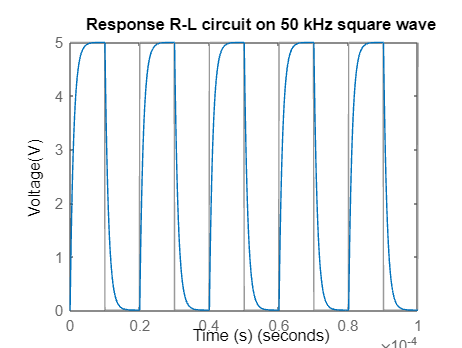

% The stability of this program allows a steady state value of 1
% Since R and L are both positive values, the pole has a negative real part.
figure;
f = 50000;
t = 5* (linspace(0, 1/f, 1000)) ;
Vin = 5*(square (2*pi*f*t) >= 0) ;
lsim(g1, Vin, t);
title('Response R-L circuit on 50 kHz square wave')
xlabel ('Time (s)')
ylabel('Voltage(V)')

% the response of the R-L circuit reaches a steady-state value after some time
%%Therefore, the R-L circuit remains stable in response to a square wave input
%R-L circuit having a square wave input at 50 kHz.
% A square wave with an amplitude of 5 volts and a duty cycle of 50% is used to establish the input voltage 
% Vin. The R-L circuit's response to the input voltage Vin over the time vector t is simulated using the lsim function.
%%
figure;
f = 500000;
t = 5*(linspace(0, 1/f, 1000)) ;
Vin = 5*(square (2*pi*f*t) >= 0)

Vin =      5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5


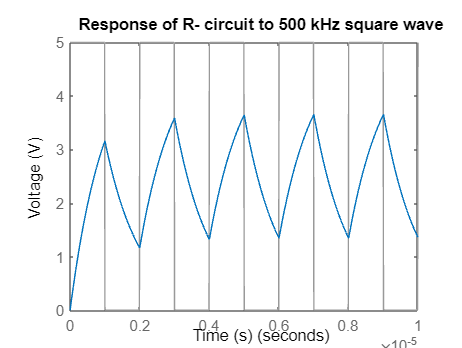

lsim(g1, Vin, t);
title('Response of R- circuit to 500 kHz square wave')
xlabel('Time (s)')
ylabel('Voltage (V)')

%simulating the reaction of the R-L circuit to a 500 kHz square wave input.
% A square wave with an amplitude of 5 volts and a duty cycle of 50% is used to establish the input voltage Vin. 
% The response of the R-L circuit to the input voltage Vin throughout the time vector is simulated using the lsim function.
% A dynamic system's settling time is defined as the time necessary for the output to attain and stabilise within a certain tolerance range.

%You may set the time period and sample rate in MATLAB by utilising functions like linspace. With charting features like plot and stem, 
% you may also see and examine signals and systems across time.

%Im going to Compare the sinewave from the 50kHz to the 500kHz RL circuit. On the graph it indicates the values in the graph is significantly different and the
%settling time on on the 50kHz is higher than the 500KHz. On the graph on the 50kHz the settling time is at 5V but to compare this
% result to 500kHz then the result is recordered at 3.5V which is a difference of 1.5V as this can make a differnece. This is the
%result of the circuit being a low pass frequency and only allows frequency
%at a low rate pass through easier, you can see 50kHz allows more signal to pass through rather 500kHz